## Introduction

This code uses a convolution approach to forecast and hindcast PFAS concentrations in groundwater discharge to stream water. However, this code is modifiable so that any mobile contaminants (i.e., the contaminant is not retarded or sorbed) can be analyzed. In its current state, this code cannot handle contaminants that decay, but this can be easily added by adding a decay term to the convolution equation.

The convolution approach requires two main inputs:

- The input history of the contaminant to the groundwater system.

- The transit time distribution (TTD) of groundwater which describes the groundwater ages present in a groundwater system.

This code is set up to create a custom input history (referred to here as an "input function") in which users can identify the start date and end date of contaminant input to the groundwater system and use age-dated groundwater samples to define the middle part of the input history.

When the convolution approach is applied to groundwater contaminants, it is common to use lumped parameter models (LPMs) to describe the TTD. These LPMs take a limited number of inputs based on the aquifer characteristics (e.g., mean age, screened interval, ratio of advection to dispersion, etc) to create a continuous TTD. However, this code forgoes the use of an LPM in favor of an empirical TTD. In an empirical TTD, only groundwater ages that have been specifically measured in the field are used to define the TTD.

## Uploading Data

Example inputs to define the TTD have been included in this package in the "GW_Ages.mat" file. In this editable file, groundwater age, the error/uncertainty associated with that groundwater age, the recharge year, and the specific discharge associated with groundwater collected in a stream bed have been included. To create your own custom TTD, simply update "GW_Ages.mat" with your own data. The code that follows also normalizes the specific discharge measurements into a variable called "TTD" which represents the relative abundance of each age in groundwater.

load GW_Ages.mat
datatable = GWAges

datatable = 20×6 table
       Sample       GWAge    GWAgeError    RechargeYear    SpecificDischargemday    SpecificDischargeUncertaintymday
    ____________    _____    __________    ____________    _____________________    ________________________________

    {'68CA'    }     6.6        1.5           2014.2              0.18153                      0.0058595            
    {'250C'    }    10.8        1.5             2010              0.52774                       0.017047            
    {'250R'    }    24.6        0.6           1996.2               0.5672                       0.018314            
    {'328C'    }       0          0           2020.8              0.87678                       0.028326            
    {'328LNoXe'}     1.8        2.1             2019               1.0

Sample = table2array(datatable(:,1));
    %Sample Locations
Age = table2array(GWAges(:,2));
    %Groundwater Ages to use for Empirical TTD
AgeConf = table2array(GWAges(:,3));
    %Uncertainty in Groundwater Age
RechargeYear = table2array(GWAges(:,4));
    %Groundwater Recharge Year
SpecDischarge = table2array(GWAges(:,5));
    %Specific Discharge measured at each point.
SpecDischargeSD = table2array(datatable(:,6));
    %Uncertainty in Specific discharge measurement.
TotDischarge = sum(SpecDischarge);
    %Sums all specific discharge measurements to calculate Σv.
TTD = SpecDischarge./TotDischarge;
    %Normalizes each specific discharge measurement by the total groundwater discharge to stream water.
NumberofSamples = numel(Sample);
    %Calculates the number of points to use in the empirical TTD.

Example inputs to define the PFAS input function are included in the "PFAS_Concentrations.mat file. This file includes columns for the concentrations (in ng/L) of various PFAS studied in Jensen et al. (2024) which used concentrations measured in age-dated groundwater samples to define the rising limb of the input function between 1982 and 2019. Columns 2 thru 19 are the actual concentrations while columns 20 thru 37 are the associated uncertainties in the same order. To use different contaminants, simply include a column for the concentration and for the error of your contaminant.

load PFAS_Concentrations.mat
datatable2 = PFASConcentrations

datatable2 = 20×37 table
       Sample       TotalPFASConcentrationngL     GenX     HydroEVEAcid    NafionByproduct2    NafionByproduct4     PEPA      PFBA     PFHpA     PFHxA     PFMOAA    PFO2HxA    PFO3OA    PFO4DA    PFO5DoDA     PFOA      PFOS     PFPeA      PMPA     TotalPFASConcentrationngLRSD     GenXRSD     HydroEVEAcidRSD    NafionByproduct2RSD    NafionByproduct4RSD    PEPARSD     PFBARSD     PFHpARSD    PFHxARSD    PFMOAARSD    PFO2HxARSD    PFO3OARSD    <s

PFASConc = table2array(datatable2(:,2:19)); %PFAS Concentrations
PFASError = table2array(datatable2(:,20:37)); %Uncertainty in PFAS Concentrations


The file "PFAS_Baseline.mat" contains estimated PFAS concentrations ingroundwater recharge before and after the main model years. In the example data from Jensen et al. (2024), row 1 is the estimated concentration of each PFAS in groundwater recharge prior to plant operations beginning in 1980 (which is assumed to be 0 ng/L) while row 2 is the concentration of PFAS in groundwater recharge after the start of 2021 for each PFAS (estimated with atmospheric deposition data obtained from the North Carolina Department of Environmental Quality). The starting concentration (row 1) and the baseline concentration (row 2) can be changed in this table (make sure each column in "PFAS_Baseline.mat" is in the same order as "PFAS_Concentrations.mat"). The dates associated with these values can be changed in the "User Defined Variables" section.

load PFAS_Baseline.mat
datatable3 = PFASBaseline

datatable3 = 2×18 table
    TotalQuantifiedngL    GenXNgL    HydroEVEngL    NafionByproduct2ngL    NafionByproduct4ngL    PEPAngL    PFBAngL    PFHpAngL    PFHxAngL    PFMOAAngL    PFO2HxAngL    PFO3OAngL    PFO4DAngL    PFO5DAOrTAFN4ngL    PFOAngL    PFOSngL    PFPeAngL    PMPAngL
    __________________    _______    ___________    ___________________    ___________________    _______    _______    ________    ________    _________    __________    _________    _________

StartConcArray = table2array(datatable3(1,:));
    %Starting concentrations of each PFAS in groundwater recharge.
BaselineArray = table2array(datatable3(2,:));
    %Ending concentrations of each PFAS in groundwater recharge.

## User Defined Variables

In this section, the user defines a series of variables to use in the convolution model. Please review the comments below each line of code for instructions on how to update these values.

PFASNumb = 1;
    %Select PFAS number to model. The key below is for the PFAS in the example code.
    %Key: Total Quantified PFAS (1), GenX (2), HydroEVE Acid (3),
    %Nafion Byproduct 2 (4), Nafion Byproduct 4 (5), PEPA (6), PFBA (7), PFHpA (8), PFHxA (9), PFMOAA (10),
    %PFO2HxA (11), PFO3OA (12), PFO4DA (13), PFO5DoDA (14), PFOA (15), PFOS
    %(16), PFPeA (17), PMPA (18).

SampleYear = 2020 + 10/12

SampleYear = 2.0208e+03

    %Date (in years) when samples were collected.
Alpha = 0.32;
    %For 95% confidence, use 0.05, for 99% confidence, use 0.01, etc...
Increment = 0.5;
    %How often (in years) to calculate flow-weighted mean output
    %concentration from the convolution approach.
E = 1960:Increment:2200;
    %Years and time step to model.
    %Currently set to model from 1960 to 2200 in 0.5 year increments
MCRuns = 2000;
    %Number of Monte Carlo simulations.

### Defining the Input Curve

The example model is currently set up to with a 5 segment PFAS input function. In the example code/data from Jensen et al. (2024), PFAS concentrations are set to 0 ng/L prior to 1980 and increased quickly (in a linear fashion) between 1980 and 1982. From 1982 to 2019, PFAS input was defined by a linear regression of the groundwater age and PFAS concentration data contained in datatable1 and datatable2. Between 2019 and 2021, PFAS concentration decreased rapidly (in a linear fashion) until they reach a baseline defined by data in datatable3.

The exact timing of each of these 5 segments can be adjusted below. The type of polynomial regression used for the middle segment (1982 to 2019 in the example code) can also be changed  using the "RegressNumb" variable. The confidence intervals of each coefficient of the polynomial regression is used to generate MonteCarlo simulations of the Input funciton later on in the LiveScript. If you wish to only vary the intercept (and not the slope) of a linear regression in Monte Carlo analysis, set "RegressNumb" to 0.

ProductionStart = 1980;
    %Start of PFAS production at the Fayetteville Works Facility
ProductionRamp = 1982;
    %years it took for emissions from production to reach the water table.

PeakYr = 2019;
    %This is the peak year in which the reduction in emissions started.
RedEnd = 2021;
    %When the plateau concentration is reached.

RegressNumb = 1;
    %1 for linear, 2 for quadratic, 3 for trinomial, 0 for linear with only
    %interept varied
Regress = {'poly1','poly2','poly3','poly4','poly5','poly6','poly7','poly8','poly9'};
if RegressNumb == 0;
    Regress = 'poly1'
end
RegressSamples = [1:15 18:20];
    %These are the samples to use in the regression for the middle segment
    %of the PFAS input function. Each number corresponds to the rows in 
    %datatable2 which each represent a different sample.


full = 1:NumberofSamples;
idx = ismember(full, RegressSamples);
UnusedSamples = full(~idx);

Baseline = BaselineArray(:,PFASNumb);
    %Baseline concentration taken from datatable3. If you want to put in a
    %custom concentration, simply set "Baseline" equal to that concentration.
StartConc = StartConcArray(:,PFASNumb);
    %Concentration before the start of PFAS input to the groundwater
    %system. This value is taken from datatable3. If you want to put in a
    %custom concentration, simply set "Baseline" equal to that concentration.



The following code is used to define the PFAS input function, but should not changed.

fittype = char(Regress(RegressNumb));
F = fit(RechargeYear(RegressSamples,:),PFASConc(RegressSamples,PFASNumb),fittype,normalize='on')

F =      Linear model Poly1:
     F(x) = p1*x + p2
       where x is normalized by mean 1997 and std 12.78
     Coefficients (with 95% confidence bounds):
       p1 =       344.7  (69.31, 620.1)
       p2 =        1294  (1026, 1562)

    %Regression statistics for middle segment of the contaminant input segment.
CoeffConf = confint(F,0.68);
    %First column contains the confidence intervals (defined by alpha) of the slope while the second column
    %contains the confidence intervals of the y-intercept.
CoeffConf = CoeffConf(2,:) - coeffvalues(F)

CoeffConf =   133.3232  129.5668


    %Calculation of the uncertainty in the slope and intercept.
MY = repmat(E,NumberofSamples,1);
    %Creates a matrix with as many rows as there are samples, while each column is a modeled half year (increment can be changed above).
ModYrs = MY-Age;
    %Calculates the recharge year for a given model year using groundwater age.
Row = size(ModYrs,1);
Col = size(ModYrs,2);
Input = zeros(Row,Col);
    %Creates an empty matrix the same size as the ModYrs matrix.

P(1) = (F(ProductionRamp) - StartConc)./(ProductionRamp-ProductionStart);
	%Slope of the linear increase from 0 ng/L in 1980 - 1981. 
P(2) = StartConc - ProductionStart.*P(1);
	%Intercept of the linear increase from 0 ng/L in 1980 - 1981. 
Q(1) = (Baseline-F(PeakYr))/(RedEnd-PeakYr);
	%Slope of the linear decrease from the peak PFAS concentration at the start of 2019 to the baseline concentration at the start of 2021. 
Q(2) = Baseline - Q(1).*RedEnd;
	%Intercept of the linear decrease from the peak PFAS concentration at the start of 2019 to the baseline concentration at the start of 2021. 


Input(ModYrs<ProductionStart) = StartConc;
    %0 ng/L until 1980.
Input(ModYrs>=ProductionRamp & ModYrs<=2019) = F(ModYrs(ModYrs>=ProductionRamp & ModYrs<=2019));
    %PFAS concentration in GW. If the model recharge year falls in 1982 - 2019, the linear regression (F) is used for that matrix entry.
Input(ModYrs>=ProductionStart & ModYrs<ProductionRamp) = ModYrs(ModYrs>=ProductionStart & ModYrs<ProductionRamp).*P(1)+P(2);
    %Linear increase from 0 ng/L in 1980 - 1981. P(1) and P(2) represent the slope and intercept, respectively, of this linear equation.
Input(ModYrs>PeakYr & ModYrs<=RedEnd) = ModYrs(ModYrs>PeakYr & ModYrs<=RedEnd).*Q(1)+Q(2);
    %Linear decrease from peak PFAS concentration at the start of 2019 to the baseline concentration at the start of 2021. Q(1) and Q(2) represent the slope and intercept, respectively of this linear equation.
Input(ModYrs>RedEnd) = Baseline;
    %Baseline concentration based on 2020 – 2022 atmospheric deposition data.
Input(Input<0) = 0;
    %Ensures that the concentration predicted by the polynomial regression in 1982 - 2019 is not negative.


## Monte Carlo Analysis

RLC(1,1:10) =  zeros; %Rising Limb Coefficients
m = length(coeffvalues(F));
RLC(1:m) = fliplr(coeffvalues(F))

RLC = 1.0e+03 *

    1.2940    0.3447         0         0         0         0         0         0         0         0


    %Creates new variable, RLC, that orders coefficients from lowest order to highest order. In this example, the left coefficient is the intercept and the coefficient on the right is the slope of a linear regression.
RLCConf = CoeffConf;
    %Reorders coefficients computed using the confint function to match RLC.
if RegressNumb == 0;
    RLCConf(2:10) = 0;
    %Makes the y-intercept the only coefficient that's varied.
end
RLCMC(1,1:10,1:MCRuns) =  zeros; %Monte Carlo Coefficients for F
for n = 1:m
    RLCMC(1,n,1:MCRuns) = normrnd(RLC(n),RLCConf(n),MCRuns,1);
end
    %Creates 2,000 Monte Carlo simulations of the slope and intercept.

RechYrMean = mean(RechargeYear(RegressSamples,:));
    %Mean recharge year for the 17 samples used for the regression (1999).
RechYrSTD = std(RechargeYear(RegressSamples,:));
    %Standard deviation of the recharge year for the 17 samples used for the regression (13.06 yr).

a = (ProductionRamp - RechYrMean)./RechYrSTD;
    %Accounts for normalization performed by the fit function.
PConc(1,1,1:MCRuns) = RLCMC(1,1,1:MCRuns) + RLCMC(1,2,1:MCRuns).*a.^1 + RLCMC(1,3,1:MCRuns).*a.^2 + RLCMC(1,4,1:MCRuns).*a.^3 + RLCMC(1,5,1:MCRuns).*a.^4 + RLCMC(1,6,1:MCRuns).*a.^5 + RLCMC(1,7,1:MCRuns).*a.^6 + RLCMC(1,8,1:MCRuns).*a.^7 + RLCMC(1,9,1:MCRuns).*a.^8 + RLCMC(1,10,1:MCRuns).*a.^9;

PMC(1,1,1:MCRuns) = (PConc(1,1,1:MCRuns) - StartConc)./(ProductionRamp - ProductionStart);
    %Slope of PFAS input in 1980 - 1981 for each Monte Carlo simulation.
PMC(1,2,1:MCRuns) = StartConc - 1980.*PMC(1,1,1:MCRuns);
    %Intercept of PFAS input in 1980 - 1981 for each Monte Carlo simulation.

b = (PeakYr - RechYrMean)./RechYrSTD;
    %Accounts for normalization performed by the fit function.
QConc(1,1,1:MCRuns) = RLCMC(1,1,1:MCRuns) + RLCMC(1,2,1:MCRuns).*b.^1 + RLCMC(1,3,1:MCRuns).*b.^2 + RLCMC(1,4,1:MCRuns).*b.^3 + RLCMC(1,5,1:MCRuns).*b.^4 + RLCMC(1,6,1:MCRuns).*b.^5 + RLCMC(1,7,1:MCRuns).*b.^6 + RLCMC(1,8,1:MCRuns).*b.^7 + RLCMC(1,9,1:MCRuns).*b.^8 + RLCMC(1,10,1:MCRuns).*b.^9;
QMC(1,1,1:MCRuns) = (Baseline - QConc(1,1,1:MCRuns))./(RedEnd - PeakYr);
    %slope of PFAS input in 2019 - 2020 for each Monte Carlo simulation.
QMC(1,2,1:MCRuns) = Baseline - QMC(1,1,1:MCRuns).*RedEnd;
    %intercept of PFAS input in 2019 - 2020 for each Monte Carlo simulation.

for n = 1:MCRuns
    AgeMC(:,:,n) = normrnd(Age,AgeConf); 
end
    %Uses uncertainty in groundwater age to determine Monte Carlo simulated ages.

for n = 1:MCRuns
    MYMC(:,:,n) = MY;
end
    %Expands MY from section 9.3 to the third dimension.
ModYrsMC = MYMC - AgeMC;
    %Determines the Monte Carlo simulated recharge year for each GW flow path for every sample half year.
MCMRY = (ModYrsMC - RechYrMean)./RechYrSTD;
    %Normalizes recharge years in ModYrsMC (used only from 1982 to 2019).
InputMC = zeros(Row,Col,MCRuns);
    %Creates empty input matrix. Any time before 1980 will have 0 ng/L.
InputRiseMC = PMC(:,2,1:MCRuns) + PMC(:,1,1:MCRuns).*ModYrsMC;
InputMC(ModYrsMC>=ProductionStart & ModYrsMC<ProductionRamp) = InputRiseMC(ModYrsMC>=ProductionStart & ModYrsMC<ProductionRamp);
    %Calculates PFAS concentration for any Monte Carlo recharge year between 1980 and 1982 and populates the InputMC matrix with these values.
InputRegressMC = RLCMC(:,1,1:MCRuns) + RLCMC(:,2,1:MCRuns).*MCMRY + RLCMC(:,3,1:MCRuns).*MCMRY.^2 + RLCMC(:,4,1:MCRuns).*MCMRY.^3 + RLCMC(:,5,1:MCRuns).*MCMRY.^4+ RLCMC(:,6,1:MCRuns).*MCMRY.^5+ RLCMC(:,7,1:MCRuns).*MCMRY.^6 + RLCMC(:,8,1:MCRuns).*MCMRY.^7+ RLCMC(:,9,1:MCRuns).*MCMRY.^8 + RLCMC(:,10,1:MCRuns).*MCMRY.^9;
InputMC(ModYrsMC>=ProductionRamp & ModYrsMC<=PeakYr) = InputRegressMC(ModYrsMC>=ProductionRamp & ModYrsMC<=PeakYr);
    %Calculates PFAS concentration for any Monte Carlo recharge year between 1982 and 2019 and populates the InputMC matrix with these values.
InputFallMC = QMC(:,2,1:MCRuns)+ QMC(:,1,1:MCRuns).*ModYrsMC(:,:,1:MCRuns);
InputMC(ModYrsMC>PeakYr & ModYrsMC<=RedEnd) = InputFallMC(ModYrsMC>PeakYr & ModYrsMC<=RedEnd);
    %Calculates PFAS concentration for any Monte Carlo recharge year between 2019 and 2021 and populates the InputMC matrix with these values.
InputMC(ModYrsMC>RedEnd) = Baseline;
    %Calculates PFAS concentration for any Monte Carlo recharge year after and 2021 and populates the InputMC matrix with these values.
InputMC(ModYrsMC<ProductionStart) = StartConc;
    %Calculates PFAS concentration for any Monte Carlo recharge year after and 2021 and populates the InputMC matrix with these values.
InputMC(InputMC<0) = 0;
    %Ensures there are no negative concentrations (relevant when regression uncertainty is high, especially in higher order polynomials).




SpecDischargeMC(1,1:NumberofSamples,1:MCRuns) = zeros;
for n = 1:NumberofSamples
SpecDischargeMC(1,n,1:MCRuns) = normrnd(SpecDischarge(n,:),SpecDischargeSD(n,:),1,MCRuns);
end
    %Creates Monte Carlo simulations of specific discharge for each sample.
SpecDischargeMC(SpecDischargeMC<0) = 0;
    %Ensures that there are no simulated negative values of specific discharge
for n = 1:MCRuns
TTDMC(:,:,n) = SpecDischargeMC(:,:,n)./sum(SpecDischargeMC(:,:,n));
end
    %Calculates the TTD for each Monte Carlo Simulation with each page (n) being a different simulation.

ConvMC = pagemtimes(TTDMC,InputMC);
    %Convolution to determine the contribution of each portion of the TTD to the flow-weighted mean (FWM) concentration.
ConvMC = sum(ConvMC,1);
    %Calculates the FWM concentration for each modeled half year.
MCAvgFWM = mean(ConvMC,[1 3]);
    %Mean FWM concentration for each half year
MCStdFWM = std(ConvMC,0,[1 3]);
    %Standard deviation FWM concentration for each half year


Figure = figure('Position',[100 100 1000 500]);
plot(RechargeYear(RegressSamples,PFASNumb),PFASConc(RegressSamples,PFASNumb),'.','MarkerSize',30,'Color',[0.3 0.6 0.8]); grid on;  hold on;
plot(RechargeYear(UnusedSamples,PFASNumb),PFASConc(UnusedSamples,PFASNumb),'.','MarkerSize',30,'Color',[0.8500 0.3250 0.0980]);
errorbar(RechargeYear,PFASConc(:,PFASNumb),AgeConf,"horizontal","LineStyle","none","Color",'k',HandleVisibility='off'); hold on
errorbar(RechargeYear,PFASConc(:,PFASNumb),PFASError,"vertical","LineStyle","none","Color",'k',HandleVisibility='off');
syms x;
z = (x - RechYrMean)./RechYrSTD

$$z = \frac{562949953421312\,x}{7192501510887067}-\frac{1124267351540003072}{7192501510887067}$$

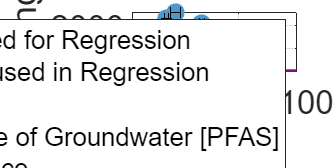

y=piecewise(x<ProductionStart, 0, ...
    x>=ProductionStart & x<ProductionRamp & (P(1)*x + P(2))>=0,(P(1)*x + P(2)), ...
    x>=ProductionStart & x<ProductionRamp & (P(1)*x + P(2))<0,0, ...
    x>ProductionRamp & x<=PeakYr & (RLC(1) + RLC(2).*z + RLC(3).*z^2 + RLC(4).*z^3 + RLC(5).*z^4 + RLC(6).*z^5 + RLC(7).*z^6 + RLC(8).*z^7 + RLC(9).*z^8 + RLC(10).*z^9)>=0, RLC(1) + RLC(2).*z + RLC(3).*z^2 + RLC(4).*z^3 + RLC(5).*z^4 + RLC(6).*z^5 + RLC(7).*z^6 + RLC(8).*z^7 + RLC(9).*z^8 + RLC(10).*z^9, ...
    x>=ProductionRamp & x<=PeakYr & (RLC(1) + RLC(2).*z + RLC(3).*z^2 + RLC(4).*z^3 + RLC(5).*z^4 + RLC(6).*z^5 + RLC(7).*z^6 + RLC(8).*z^7 + RLC(9).*z^8 + RLC(10).*z^9)<0,0, ...
    x>PeakYr & x<=RedEnd, Q(1).*x + Q(2), ...
    x>RedEnd,Baseline);

MCAvgMinusStd = MCAvgFWM-MCStdFWM;
MCAvgMinusStd(MCAvgMinusStd<0) = 0;
fplot(y,'r-','LineWidth',2), xlim([1970 2030]);
plot(E,MCAvgFWM,'-','LineWidth',2,'Color',[0.4940 0.1840 0.5560])
plot(E,MCAvgFWM+MCStdFWM,'--','LineWidth',1,'Color',[0.5 0 0.5])
plot(E,MCAvgMinusStd,'--','LineWidth',1,'Color',[0.5 0 0.5],'HandleVisibility','off')

xlabel('Year'); ylabel('PFAS ng/L'); set(gca,'FontSize',18)
xlim([1960 2100]);


legend({'Samples Used for Regression','Samples Unused in Regression',"PFAS Input",'Best Estimate of Groundwater [PFAS]',"1\sigma Confidence"},'Location',"NE",FontSize=14)